%Daten einlesen
data=readtable("Messwerte_MSA2_Micha.xlsx");

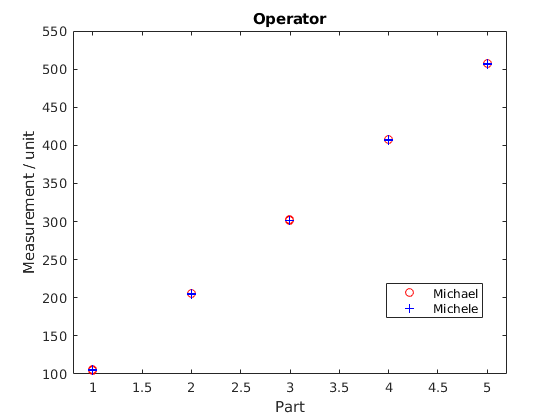

%gruppiertes Streudiagramm
gscatter(data.Part,data.Measurement,data.Operator,"rbg","o+x")
xlabel("Part")
ylabel("Measurement / unit")
title("Operator")

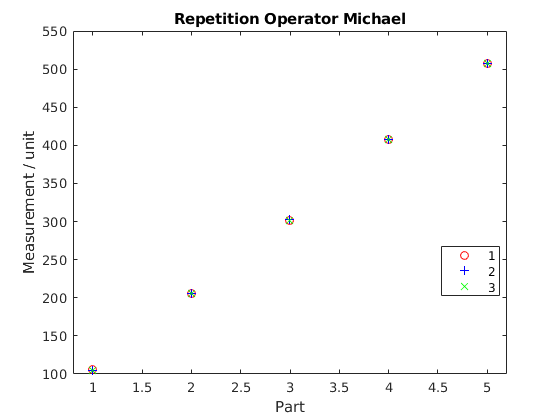

%nur Operator Michael
gscatter(data.Part(1:15),data.Measurement(1:15),data.Repetition(1:15),"rbg","o+x")
title("Repetition Operator Michael")
xlabel("Part")
ylabel("Measurement / unit")

%Daten visualisieren
boxplot(data.Measurement,{data.Part,data.Operator},"Colors","rg")
legend(findobj(gca,'Tag','Box'),'Michele','Michael')

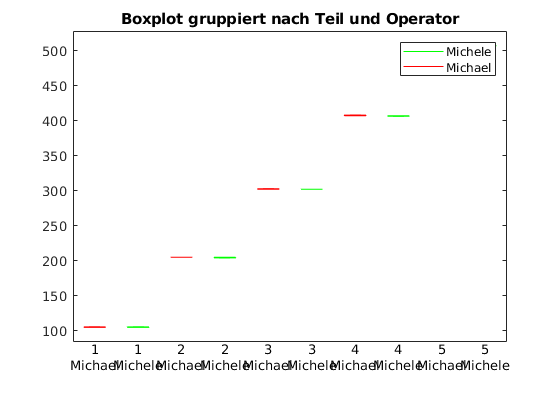

title("Boxplot gruppiert nach Teil und Operator")

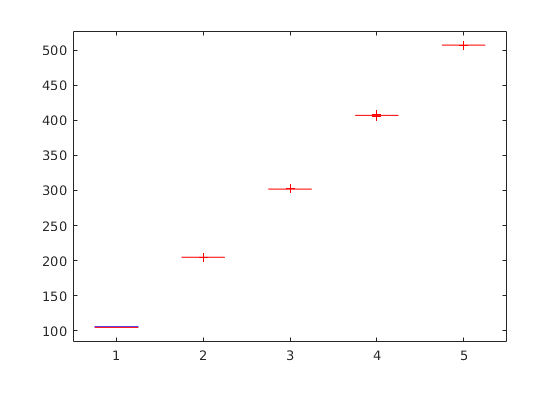

boxplot(data.Measurement,data.Part)

title("Teile")
boxplot(data.Measurement,data.Operator)
title("Operator")

%GageR&R durchführen
gagerr(data.Measurement,{data.Part,data.Operator})

    {'Source'           }    {'Variance'  }    {'% Variance'}    {'sigma'   }    {'5.15*sigma'}    {'% 5.15*sigma'}
    {'Gage R&R'         }    {[    0.2500]}    {[9.8961e-04]}    {[  0.5000]}    {[    2.5750]}    {[      0.3146]}
    {'  Repeatability'  }    {[    0.2083]}    {[8.2468e-04]}    {[  0.4564]}    {[    2.3506]}    {[      0.2872]}
    {'  Reproducibility'}    {[    0.0417]}    {[1.6494e-04]}    {[  0.2041]}    {[    1.0512]}    {[      0.1284]}
    {'   Operator'      }    {[    0.0417]}    {[1.6494e-04]}    {[  0.2041]}    {[    1.0512]}    {[      0.1284]}
    {'Part'             }    {[2.5262e+04]}    {[   99.9990]}    {[158.9406]}    {[  818.5441]}    {[     99.9995]}
    {'Total'            }    {[2.5262e+04]}    {[       100]}    {[158.9414]}    {[  818.5481]}    {0×0 char      }

Number of distinct categories (NDC):450
% of Gage R&R of total variations (PRR):  0.31
Note: The last column of the above table does not have to sum to 100%


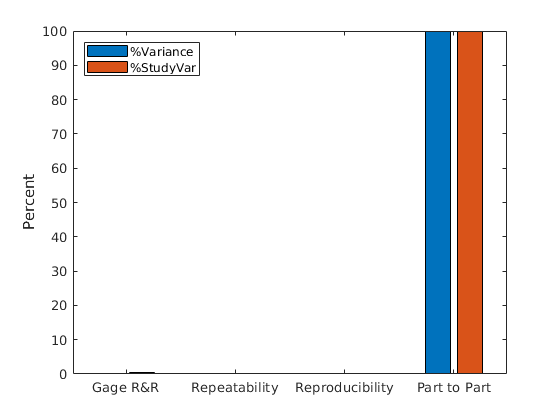

legend('Location',"northwest")